%% Load Image Dataset
imds=imageDatastore('/Users/ishug/Desktop/hw3/q7_code/q7_image/office_images','IncludeSubfolders',true,'LabelSource','foldernames');

% inspect the number of images per category, as well as category labels
tbl=countEachLabel(imds)

tbl = 5×2 table
      Label       Count
    __________    _____

    backpack       10  
    calculator     10  
    pen            10  
    printer        10  
    scissors       10  


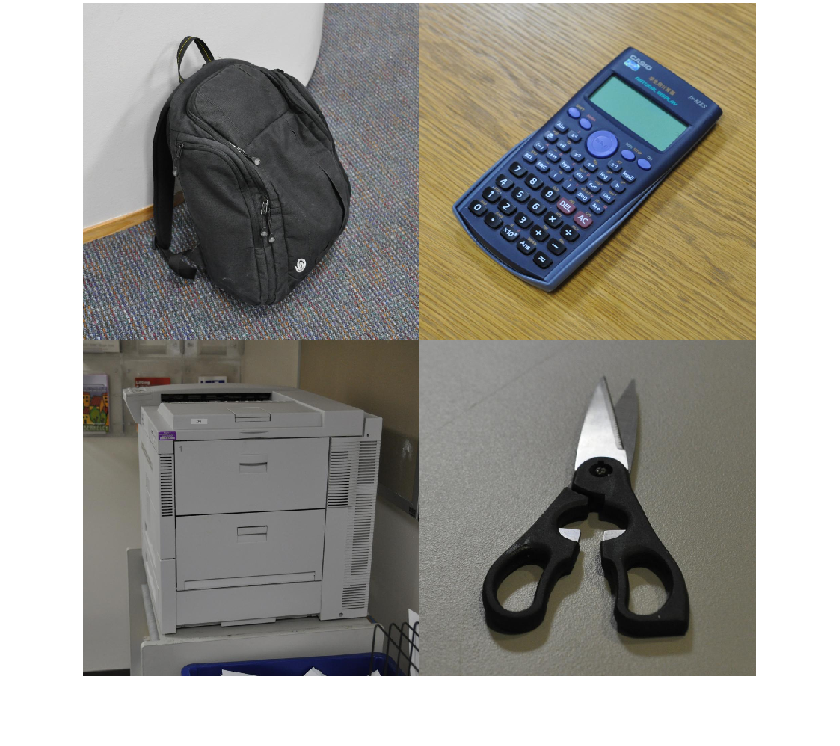


% visualization
figure
montage(imds.Files(1:16:end))


%% Prepare Training and Validation Image Sets
[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');

%% Create a Visual Vocabulary and Train an Image Category Classifier

% Creating Bag-Of-Features.
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: backpack
* Image category 2: calculator
* Image category 3: pen
* Image category 4: printer
* Image category 5: scissors
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 30 images...done. Extracted 1875000 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 1500000
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 42/100 iterations (~4.95 seconds/iteration)...converged in 42 iterations.

* Finished creating Bag-Of-Features




% Encoding images using Bag-Of-Features.
img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


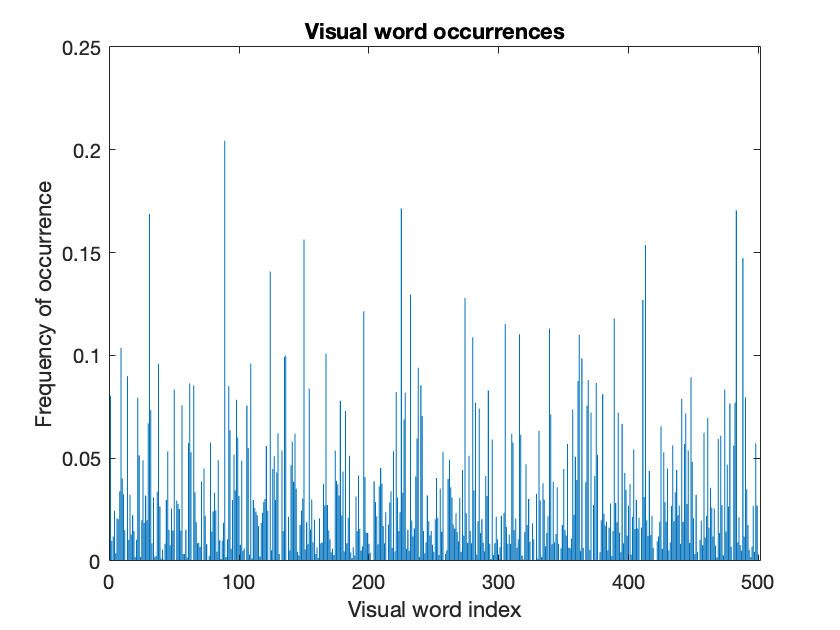


% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')


%% Training an image category classifier for 5 categories.
categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Error using toolboxdir (line 54)
Could not locate the base directory for stats.

Error in vision.internal.requiresStatisticsToolbox (line 7)
if ~isfolder(toolboxdir('stats'))

Error in 


%% Evaluate Classifier Performance

% on training set
confMatrix = evaluate(categoryClassifier, trainingSet);

% on validation set
confMatrix_val = evaluate(categoryClassifier, validationSet);

% Compute average accuracy
avg_acc = mean(diag(confMatrix_val));

%% instance study
% read an image
img = imread(fullfile('/Users/ishug/Desktop/hw3/q7_code/q7_image/office_images','backpack','frame_0001.jpg'));
figure
imshow(img)

% run classification
[labelIdx, scores] = predict(categoryClassifier, img);
labelName = categoryClassifier.Labels(labelIdx);
disp(labelName)
